# Non-Linear Total Variation (TV) Image Denoising

In PDE-based image denoising, using a simple Laplacian/diffusion approach produces overly smoothed images that fail to preserve important edges in the data. Total Variation (TV) regularization overcomes this limitation by preserving sharp boundaries. This is solved iteratively via the following PDE for $k \geq 0$:


$$-\alpha \nabla \cdot \left( \frac{1}{|\nabla u^{k}|} \nabla u^{k+1}(x,y) \right) + u^{k+1}(x,y) = u^{0}(x,y) \quad  \text{in } \Omega = (0,1)^2$},$$


The parameter $\alpha > 0$ controls the degree of smoothing applied. The diffusion coefficient $\frac{1}{|\nabla u^k|}$ preserves edges by penalizing gradients in high-contrast regions, which decreases the local diffusion rate. Conversely, in flat regions where the gradient is small, it increases diffusion to perform standard smoothing. 

We employ a finite difference scheme, solving using the Conjugate Gradient method. The equations can be formulated into the following linear system:


$$A \big( u^k \big) u^{k + 1} = u^0$$


where $A \big( u^k \big)$ depends on the current values of $u^k$. The matrix is symmetric positive-definite and shares the same sparsity pattern as the $5$-point stencil 2D Laplacian matrix.

% Variables:
n = 512;
n_s_ratio = 1;
K = 8;
alpha = 4.096 / n;
maxiter = 2000;
tol = 1e-3;

results = zeros(K + 1, 2);
row_labels = ["k = " + string(1:K), "Total"];
col_labels = ["Iterations", "Runtime (s)"];

% Setup image:
[image, noisy] = set_image(n, n_s_ratio); % Can set a seed, see set_image.m
b = noisy(:);
x = b;

### Acceleration via Preconditioned Conjugate Gradient

As the outer iteration $K$ progresses, the system $A \big( u^k \big)$ becomes increasingly ill-conditioned around sharp intensity transitions (where $\vert{}\nabla u\vert{} \to \infty$).

To maintain fast convergence at high grid resolutions ($n \ge 512$), we precondition the system using an **Incomplete Cholesky factorization (**`ichol`**) with thresholding**:


$$M = L L^T \approx A \big( u^k \big)$$


Inside the custom PCG function (`pcg_solver.m`), preconditioned residual steps $z = \big( LL^T \big)^{-1} r$ are efficiently calculated via forward and backward triangular solves.

% TV denoising:
for k = 1:K
    A = form_matrix(x, alpha);
    L = ichol(A, struct(type = "ict", droptol = 1e-2));

    tic;
    [x, iter] = pcg_solver(A, b, x, L, L', maxiter, tol);
    results(k, 2) = toc;
    results(k, 1) = iter;
end

results(K + 1, :) = sum(results);
array2table(results, RowNames = row_labels, VariableNames = col_labels)

ans = 9×2 table
             Iterations    Runtime (s)
             __________    ___________

    k = 1         6          0.17149  
    k = 2        17          0.49546  
    k = 3        51           1.1457  
    k = 4       104           2.1759  
    k = 5       155           4.5365  
    k = 6       209           6.4686  
    k = 7       237           5.7691  
    k = 8       192           5.8668  
    Total       971            26.63  

	Get insights using Copilot


### **Convergence, Runtime, and Results**

For a $512 \times 512$ grid ($N = 262,144$ total unknowns) with a noise-to-signal ratio of $1.00$,

**Outer Loop Convergence:**

The inner iterations stabilize across $K = 8$ steps. In early outer iterations ($k = 1, \, 2, \, 3$), the linear system is well-behaved, requiring few inner PCG steps. As sharp intensity boundaries form in later steps, local gradients steepen, causing inner PCG iterations to peak ($k = 4, \, 5, \, 6$) before stabilizing ($k = 7, \, 8$).

**Computational Efficiency:**

The total execution time across all $8$ outer steps is less than $50$ seconds, with approximately$1000$ cumulative PCG iterations. Incomplete Cholesky preconditioning reduces the iteration count by orders of magnitude compared to standard Jacobi/GS/SOR methods.

**Visual Edge Preservation:**

As shown in the denoised image, TV regularization successfully removes heavy noise while retaining sharp ellipse boundaries without bleeding or edge blurring.   

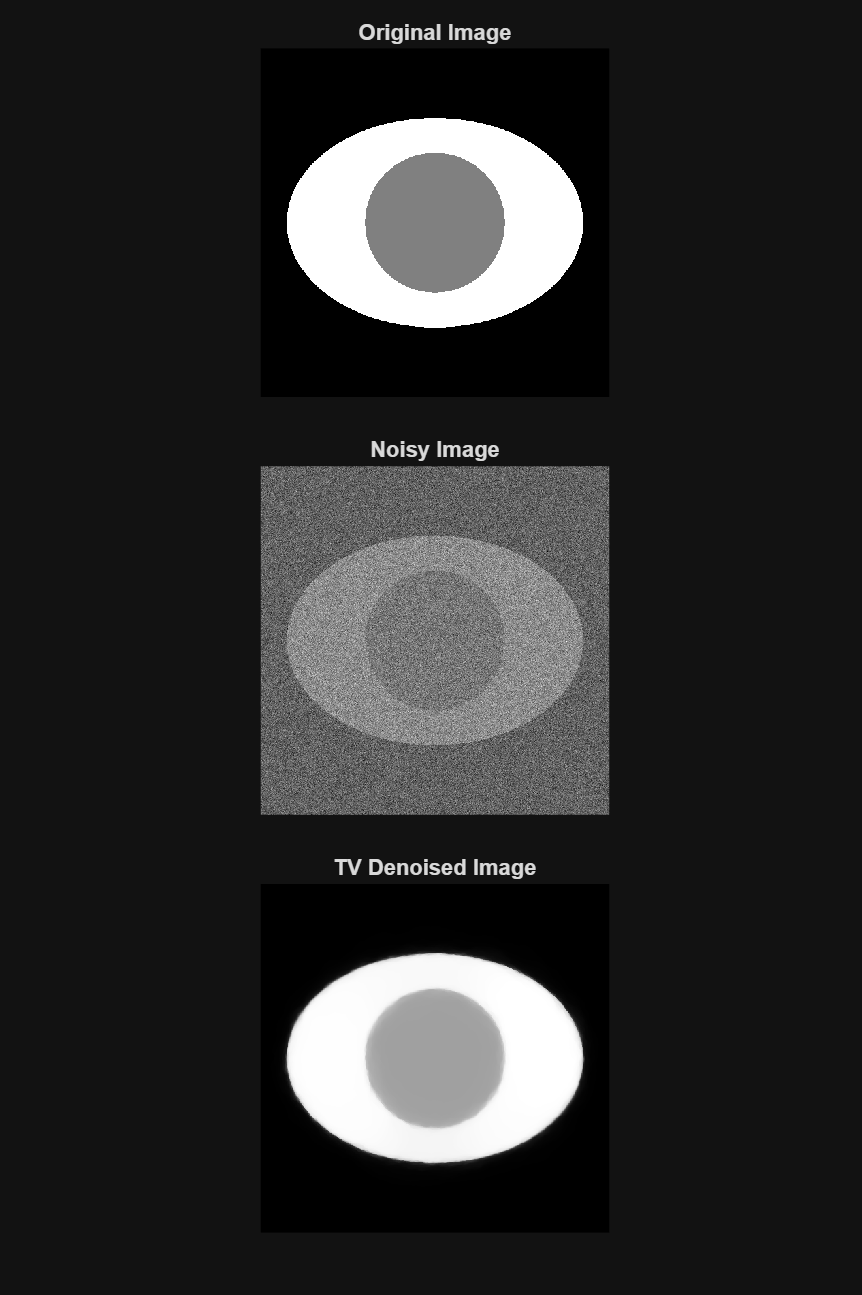

% Plot:
data = {image, noisy, reshape(x, n, n)};
titles = ["Original Image", "Noisy Image", "TV Denoised Image"];

fig = figure(Position = [100, 100, 800, 1200]);
tiledlayout(3, 1, TileSpacing = "compact", Padding = "compact");
colormap gray;

for i = 1:3
    nexttile;
    imagesc(data{i});
    title(titles(i));
    axis square off;
end

exportgraphics(fig, "denoised_images.png", BackgroundColor = "current");